# Random Variables, Distributions, and Sampling

**Suggested Prework**

[Probability: The Basics](matlab:open('./probabilityIntro.mlx')) – Review the terminology and definitions associated with the fundamentals of probability theory.

You can this script in a controls-only mode by using the **Hide code **  button or view the code by using the **Output inline**    button on the **View** tab of the MATLAB toolstrip.

## Random Variables

A random variable assigns a measurable value to every outcome of a random experiment or a random process. Typically, the measurable values are real numbers.

**Task.** Open the app `randomVariableApp` to generate your random variables*.*

randomVariableApp
 

  **Try**

- Follow the instructions in the app to create a new random variable $X$. Assign different group of outcomes in the probability space to other real values $n$ of your choice.

- Based on the classical perspective, what is the probabilty of $X$ taking the value $n$ for every possible value of $n$?

- Click **Sample **to generate an empirical distribution of $X$; that is, $P\left(X=n\right)$ for all $n\in X$. Study the distribution plot.

- Create a random variable in the app's probability space to resemble the following distribution: 

              

              Example app instance

              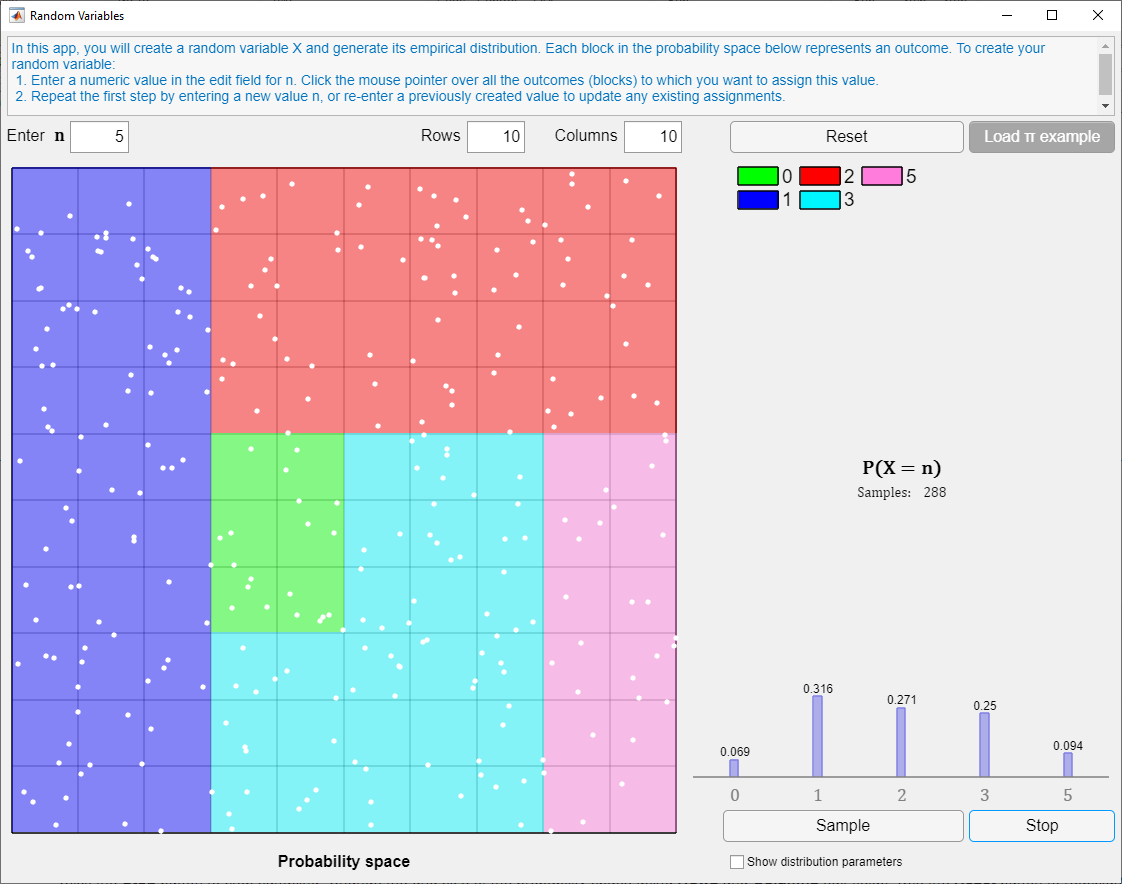

Click the **Stop** button to stop sampling. Change the grid size of the probability space using **Rows** and **Columns **edit fields. Use the **Reset **button to reassign all outcomes to 0 and clear the distribution plot.

 ***Reflect***

- *After a large number of samples (say,1000), do the probabilities in the empirical distribution match up with your expectation?*

### Expectation and Variance

The distribution of a random variable is often characterized by two parameters—expected value and variance.

Expected value of a random variable is a measure of the distribution's "center." Mathematically, it is a probability-weighted sum of all the values that the random variable can take.

                       
$$E\left\lbrack X\right\rbrack =\sum_{x\in X} x\;P\left(X=x\right)$$


Variance of a random variable measures the distribution's "spread"; that is, how far the values typically lie from the expected value. Mathematically, it is an average of the squared distances between the values that the variable can take from the random variable's expected value.

                    
$$\textrm{Var}\left\lbrack X\right\rbrack =E\left\lbrack \left(X-{\left.E\left\lbrack X\right\rbrack \right)}^2 \right\rbrack \right.$$


                                
$$=\sum_{x\in X} {\left(X-E\left(X\right)\right)}^{2\;} P\left(X=x\right)$$


**Task.** Open the app `randomVariableApp` to study the expected value and variance of a random variable.

randomVariableApp
 

  **Try**

- *Check ****Show distribution parameters ****in the app****.***

- *Click ****Load π example**** button in the app. Observe the random variable's values and generate its empirical distribution by clicking the ****Sample**** button.*

              *Example app instance*

              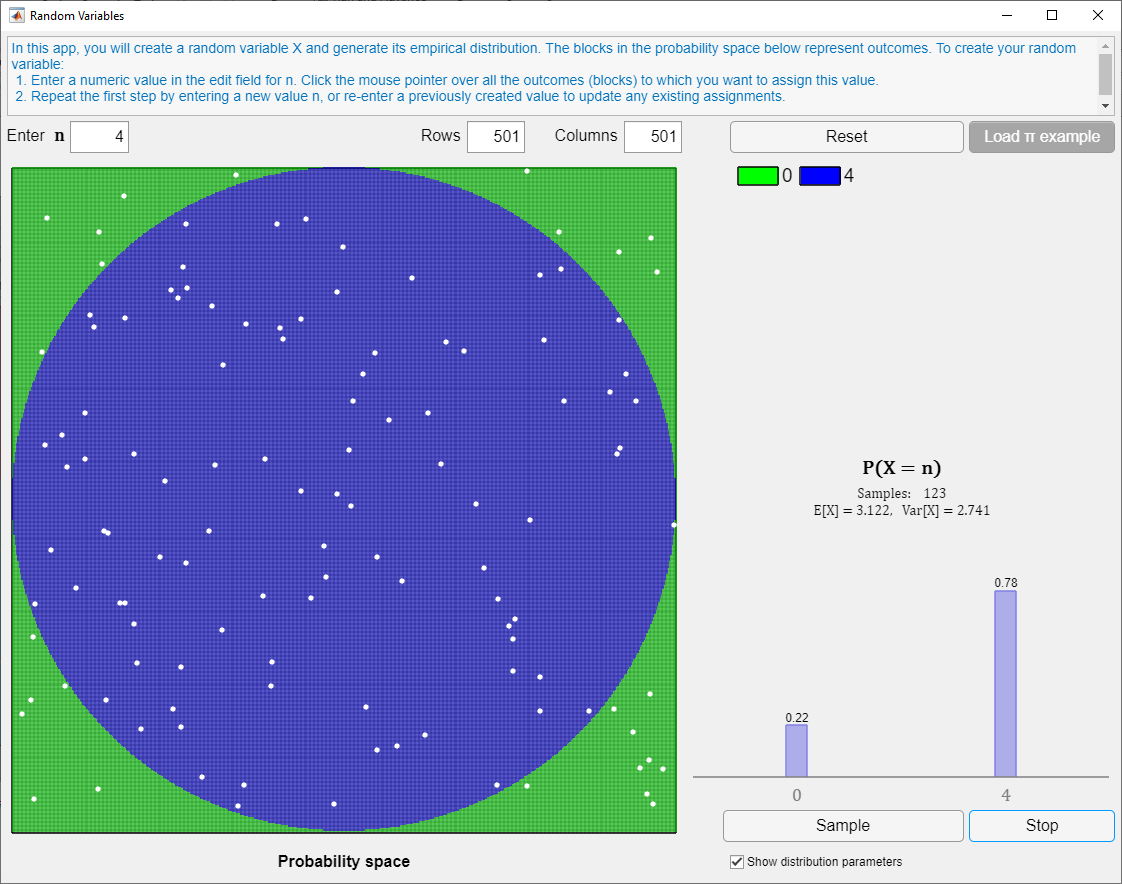

 ***Reflect***

- *After a very large number of samples,* *does the expected value of *$X$*; that is, *$E\left\lbrack X\right\rbrack$* approach the value of 3.1416? Why?*

### Discrete Random Variables

For random processes with discrete outcomes, like the roll of a die or a coin toss, we define a discrete random variable that can take an exact value. The distribution of a discrete random variable is characterized by a *probability mass function* (PMF).

                    
$$f\left(x\right)\;=\;P\left(X=n\right)$$


When evaluated at $n$, the cumulative distribution function is the probability that the discrete random variable will take a value less than or equal to $n$.

                    
$$F\left(x\right)\;=\;P\left(X\le n\right)$$


For example, a discrete uniform random variable follows a distribution where every value is equally likely. This roll of a fair die, the toss of a fair coin, and drawing a single card from a deck can all be described by a uniform distribution.

                    $f\left(x\right)=\frac{1}{N}$, where $N$ is the total number of possible discrete values 

**Example. **If you roll a six-sided die, what is the probability of landing on a number greater than or equal to 4?

**Task.** Click the **Run** button to visualize the discrete random variable for the roll of a single die.

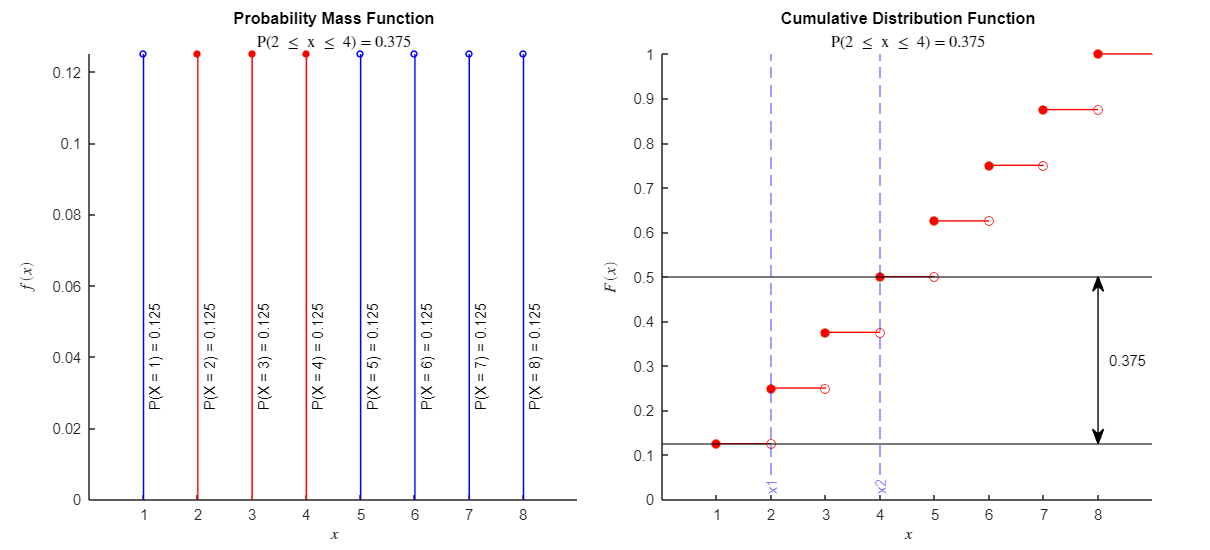

N = 8;                         % number of possible outcomes
a = 2;                         % min of interval
b = 4;                         % max of interval
  
figure("Position",[0 0 1100 500])
plotUnifDist(N,a,b);

  **Try**

- Use the edit fields to set values for `a`, `b`, and `N` to answer this question: What is the probability that an eight-sided die roll will land between 2 and 5 (inclusive)?

 ***Reflect***

- *One of the ways the uniform distribution manifests is when sampling randomly from a population. This approach is often used to approximate the preferences or characteristics of a larger population based on a subset of the population (e.g. election polling). In an ideal scenario, every member of the population is **equally likely** to be chosen as a sample. What are some practical considerations of this approach? *

- *To learn more about other commonly encountered discrete random variables and distributions, refer to the courseware module *[*Descriptive Statistics and Probability Distributions*](https://www.mathworks.com/matlabcentral/fileexchange/95463-descriptive-stats-and-probability)*.*

### Continuous Random Variables

Many random processes have continuous-valued outcomes. For instance, consider the weight of a human of a given age. Because there are infinite possible values, no single numeric value of weight has a non-zero probability of occurring. A continuous random variable never takes on an exact value; that is, $P\left(X=x\right)=0$. For such variables, it makes more sense to specify the probability of falling within a range of values. The probability of the weight being exactly 58 kg is 0. However, there is a finite probability of the weight being between 58 and 58.1 kg.

The *probability density function (PDF)* is the continuous counterpart to the PMF for discrete variables. However, evaluating the PDF at a specific $x$ does not give you a valid probability. Instead, these can be interpreted as relative likelihoods. To get a valid probability, you must integrate the PDF over a range of values. 

                    
$$P\left(\mathrm{x_1}<x<\mathrm{x_2}\right)=\int_{\mathrm{x_1}}^{\mathrm{x_2}} f\left(x\right)\mathrm{d}x\;$$


The *cumulative distribution function (CDF), when evaluated at a value *$x$, gives the area under the PDF from $-\infty$ to $x$. In other words, CDF gives the probability that the continuous random variable will take a value less than or equal to $x$.

                    $F\left(x\right)$ = $P\left(X\le x\right)$

For example, the normal distribution or the bell curve is one of the most widely encountered distributions. Its PDF is characterized by the parameters $\mu$ (mean) and $\sigma$ (standard deviation). Different values of these parameters describe different normally distributed random variables.

                    
$$f\left(x\right)=\frac{1}{\sigma \sqrt{2\pi \;}}e^{\frac{{-\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


**Example. **The average monthly salary of government employees in a certain town is $2600, with a standard deviation of $500. If you pick an employee at random, what is the probability their salary is between $3000 and $4000?

**Task.** Click the **Run** button to visualize the continuous random variable for the salaries of government employees.

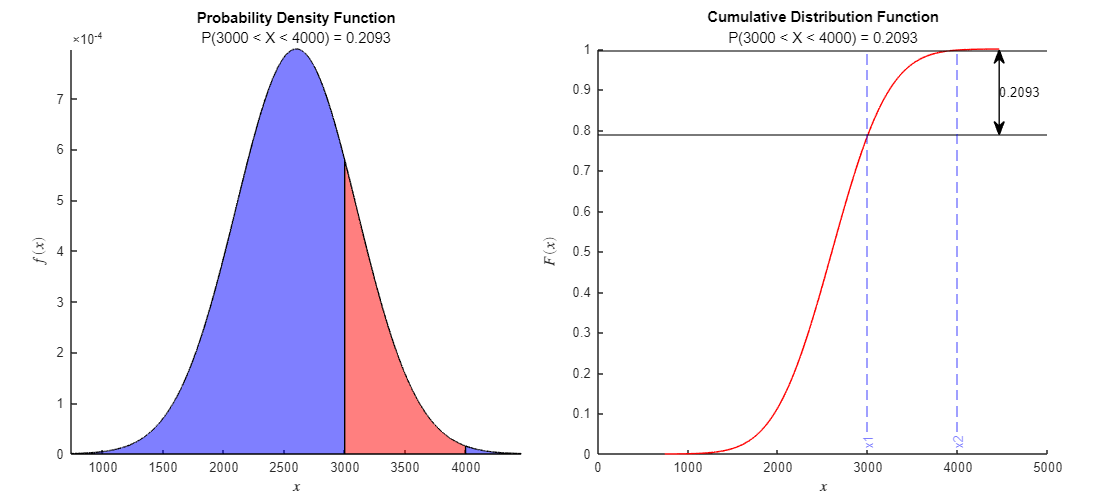

mu    = 2600;           % parameter of the distribution
sigma = 500;           % parameter of the distribution
x1    = 3000;           % min of interval
x2    = 4000;           % max of interval
  
figure("Position",[0 0 1100 500])
plotNormDist(mu,sigma,x1,x2)

 ***Reflect***

- *What is the maximum possible value that any cumulative distribution function can produce? Why?*

- *To learn more about other commonly encountered continuous random variables and distributions, refer to the courseware module *[*Descriptive Statistics and Probability Distributions*](https://www.mathworks.com/matlabcentral/fileexchange/95463-descriptive-stats-and-probability)*.*

## Central Limit Theorem

The Central Limit Theorem provides the foundational basis for drawing inferences from unknown random processes by sampling. The theorem says that the averages of samples taken from a large population follow an approximately normal distribution, regardless of the shape and type of the underlying population distribution. This is why the normal distribution or the bell-shaped curve is ubiquitous in mathematics, statistics, and data science.

As the sample size gets larger, the distribution of the sample averages tends towards a narrow and perfectly normal distribution. This normal distribution of sample means is also called the *sampling distribution*. With larger sample sizes, the mean of the *sampling distribution* starts approaching the true population mean.

**Task. **Click the **Run** button to simulate the central limit theorem with a known underlying population distribution. Verify whether the fitted normal distribution PDF (red) is a good representation of the histogram (pink).

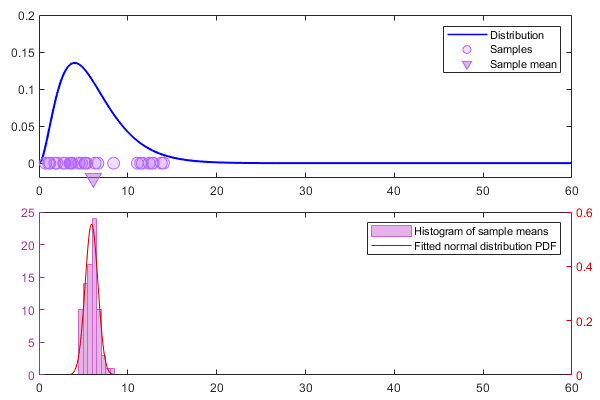

alpha =    3;       % parameter of the underlying gamma distributed population
beta =      2;       % parameter of the underlying gamma distributed population
numSamples =30;        % number of samples
numDraws =  80;       % number of draws
 
figure("Position",[0 0 600 400])
centralLimitTheorem(alpha,beta,numSamples,numDraws)

  **Try**

- Decrease the number of samples to `10` using the slider for `numSamples`, and click **Run**`.` How well does the normal distribution PDF represent the histogram of sample means?

- Increase the number of samples to `50` using the slider for `numSamples`, and click **Run**. How well does the normal distribution PDF represent the histogram of sample means?

- Modify the underlying population distribution by changing the parameters `alpha` and `beta`. Repeat the experiment.

 ***Reflect***

- *Are there any conditions of the underlying population distribution where the central limit theorem does not seem to hold, even with a large number of samples?*

## Helper Functions

function plotUnifDist(n,x1,x2)
% PLOTUNIFDIST(N,X1,X2) plots a uniform distribution PDF and CDF, along with P(X1 <= x <= X2)
% N = sample size
% X1 min of interval
% X2 max of interval

if ~(x1 <= x2)
    error("The lower limit of the interval must be less than or equal to the upper limit.")
end

% Initialize tiled layout for plotting
tiledlayout(1,2,"TileSpacing","compact","Padding","compact");

% Plot the pmf on the first tile
nexttile(1);
x = 1:n;
y = unidpdf(x,n);
y1 = unidcdf(x1-1,n);
y2 = unidcdf(x2,n);
p = round(y2-y1,4);

hold on
stem(x(x<x1 | x>x2),y(x<x1 | x>x2),"b","LineWidth",1,"MarkerSize",4); % draw pdf
stem(x(x>=x1 & x<=x2),y(x>=x1 & x<=x2),"r","filled","LineWidth",1,"MarkerSize",4) % use red for x in [a,b]
hold off

if n <= 20 % label stems for small n
    txt = "P(X = "+num2str(x')+") = "+num2str(round(y',4));
    text(x+0.2,y.*0.2,cellstr(txt),"rotation",90);
end
axis([min(x)-1,max(x)+1,0,inf])   % adjust x-axis to fit labels
xticks(x)
xlabel("$x$","Interpreter","latex")
ylabel("$f(x)$","Interpreter","latex")
str = "P("+ num2str(x1)+ " $\leq$ "+"x"+" $\leq$ "+num2str(x2)+") = "+num2str(p);
title("Probability Mass Function")
subtitle(str,"Interpreter","latex")


nexttile(2);
X = [x,max(x)+10];
Y = unidcdf(X,n);
hl = scatter(X(1:end-2)+1,Y(1:end-2),"o","MarkerEdgeColor","r");
hold on
scatter(X,Y,"o","MarkerFaceColor","r");
for k=1:length(X)-1
    plot(X(k:k+1),[Y(k) Y(k)],"r-");
end

yline(y2,"k-");
yline(y1,"k-");
xline(x1,"b--","x1","LabelVerticalAlignment","bottom","LabelHorizontalAlignment","center","Alpha",0.5)
xline(x2,"b--","x2","LabelVerticalAlignment","bottom","LabelHorizontalAlignment","center","Alpha",0.5)
ha = annotation("doublearrow");
ha.Parent = hl.Parent;
ha.X = [n n];
ha.Y = [y1 y2];
text(n+0.2,y1+p/2,num2str(p));
hold off
axis([min(x)-1,max(x)+1,0,inf])   % adjust x-axis to fit labels
xticks(x)
set(gca,"Box","off")
xlabel("$x$","Interpreter","latex")
ylabel("$F(x)$","Interpreter","latex");
title("Cumulative Distribution Function")
subtitle(str,"Interpreter","latex")

end

function plotNormDist(mu,sigma,x1,x2)
% PLOTNORMDIST(MU,SIGMA,X1,X2) plots the normal distribution PDF and CDF, along with P(X1 < x < X2)
% MU is the mean
% SIGMA is the standard deviation
% X1 min of interval
% X2 max of interval

% Initialize tiled layout for plotting
tiledlayout(1,2,"TileSpacing","compact","Padding","compact");

if ~(x1 <= x2)
    error("The lower limit of the interval must be less than or equal to the upper limit.")
end
% Plot the PDF of the distribution in the first tile.
nexttile(1);
l=round(norminv(0.0001,mu,sigma));    % lower bound for the distribution plot
r=round(norminv(0.9999,mu,sigma));    % upper bound for the distribution plot
res = 0.1;                            % resolution
x = unique([(l:res:r),x1,x2]);        % x axis values to compute pdf/cdf over
y = normpdf(x,mu,sigma);              % compute pdf
y1 = normcdf(x1,mu,sigma);            % compute cdf for lower interval limit
y2 = normcdf(x2,mu,sigma);            % compute cdf for upper interval limit
p = round(y2-y1,4);                   % subtract cdf values to compute probability
% Create the shaded region to show the area under the curve for the input
% interval
hold on
left = find(x<=x1);                 
middle = find(x>=x1 & x<=x2);
right = find(x>=x2);
fill([x(left),fliplr(x(left))],[zeros(1,numel(left)),fliplr(y(left))],"b","FaceAlpha",0.5)
fill([x(middle),fliplr(x(middle))],[zeros(1,numel(middle)),fliplr(y(middle))],"r","FaceAlpha",0.5)
fill([x(right),fliplr(x(right))],[zeros(1,numel(right)),fliplr(y(right))],"b","FaceAlpha",0.5)
hold off
% Set axis properties and annotate
axis([l,r,-inf,inf])
title("Probability Density Function")
subtitle("P("+ num2str(x1)+" < X < "+num2str(x2)+") = "+num2str(p))
xlabel("$x$","Interpreter","latex")
ylabel("$f(x)$","Interpreter","latex")

% Plot the CDF of the distribution in the second tile.
nexttile(2);
Y = normcdf(x,mu,sigma);             % compute cdf for the entire range of x
hl = plot(x,Y,"r-");                 % plot cdf
% Annotate plot to show the probability of the interval provided
hold on
yline(y2,"k-");
yline(y1,"k-");
xline(x1,"b--","x1","LabelVerticalAlignment","bottom","LabelHorizontalAlignment","center","Alpha",0.5)
xline(x2,"b--","x2","LabelVerticalAlignment","bottom","LabelHorizontalAlignment","center","Alpha",0.5)
ha = annotation("doublearrow");
ha.Parent = hl.Parent;
ha.X = [r r];
ha.Y = [y1 y2];
text(r+0.2,y1+p/2,num2str(p));
hold off
set(gca,"Box","off")
title("Cumulative Distribution Function")
subtitle("P("+num2str(x1)+" < X < "+num2str(x2)+") = "+num2str(p))
xlabel("$x$","Interpreter","latex")
ylabel("$F(x)$","Interpreter","latex");
end

function centralLimitTheorem(alpha,beta,numSamples,numDraws)
% CENTRALLIMITTHEOREM(ALPHA,BETA,NUMSAMPLES,NUMDRAWS) illustrates the
% central limit theorem by drawing NUMSAMPLES number of samples from a
% gamma distribution with parameters ALPHA and BETA. It repeats the
% sampling NUMDRAWS number of times and generates a histogram of all the
% means.

% Generate data distributed according to gamma distribution with parameters
% alpha and beta.
pd1 = makedist("Gamma","a", alpha,"b",beta);
x = 0:0.1:60;
pdfGamma = pdf(pd1,x);

% Initialize tiled layout of plots.
tiledlayout(2,1,"TileSpacing","compact","Padding","compact");

% Plot the gamma distribution pdf, samples, and the sample mean on the
% first tile.
nexttile
plot(x,pdfGamma,"b-","LineWidth",1.2,"DisplayName","Distribution");
xlim([0 max(x)])
ylim([-0.02 0.2])
samples = random(pd1,1,numSamples);
hold on
P2 = scatter(samples,zeros(size(samples)),"o","MarkerEdgeColor",[0.7 0.4 1],"MarkerFaceColor",[0.7 0.4 1],"MarkerFaceAlpha",0.2,"XDataSource","samples","SizeData",80,"DisplayName","Samples");
P3 = scatter(mean(samples),-0.02,"v","MarkerEdgeColor",[0.7 0.4 0.9],"MarkerFaceColor",[0.7 0.4 0.9],"MarkerFaceAlpha",0.5,"SizeData",110,"DisplayName","Sample mean");
hold off
legend

% Plot the histogram of sample means and the fitted normal distribution pdf
% on the second tile. The left y-axis indicates histogram counts and the
% right y-axis is used for the PDF.
sampleAvg = mean(samples);
nexttile;
colororder([0.6 0.2 0.6; 0.8 0 0])
yyaxis left
H = histogram(sampleAvg,"BinMethod","scott","EdgeColor",[0.8 0.4 0.8],"FaceColor",[0.8 0.4 0.8],"FaceAlpha",0.5,"DisplayName","Histogram of sample means");
xlim([0 max(x)])
ytickformat("%i")
pd2 = fitdist([sampleAvg;sampleAvg],"Normal"); % repeating the first value twice to create a valid pdf
pdfNorm = pdf(pd2,x);
yyaxis right
hold on
P4 = plot(x,pdfNorm,"-","Color",[0.8 0 0],"LineWidth",0.8,"DisplayName","Fitted normal distribution PDF");
hold off
legend

% Animate the two plots over a number of draws. 
for k = 2:1:numDraws    
    samples = random(pd1,numSamples,1);    % Generate new samples from the gamma distribution
    sampleAvg(k,1) = mean(samples);        % Append to the sample mean vector

    % Update each of the plots with new data.
    P3.XData = sampleAvg(k,1);
    H.Data = sampleAvg;
    pd2 = fitdist(sampleAvg,"Normal");
    P4.YData = pdf(pd2,x);
    refreshdata(P2,"caller")

    % Update the counts on the histogram y-axis to match the corresponding pdf normalization values (right axis)
    yyaxis right
    ytr = get(gca,"YTick");
    W = diff(H.BinEdges);                                  % Get the bin width from the bin edges
    yyaxis left
    ylim([0,ceil((ytr(end).*length(sampleAvg)).*W(1))]);   
    drawnow
    pause(0.05)
end
end
